## Sample Odometry according to camera poses

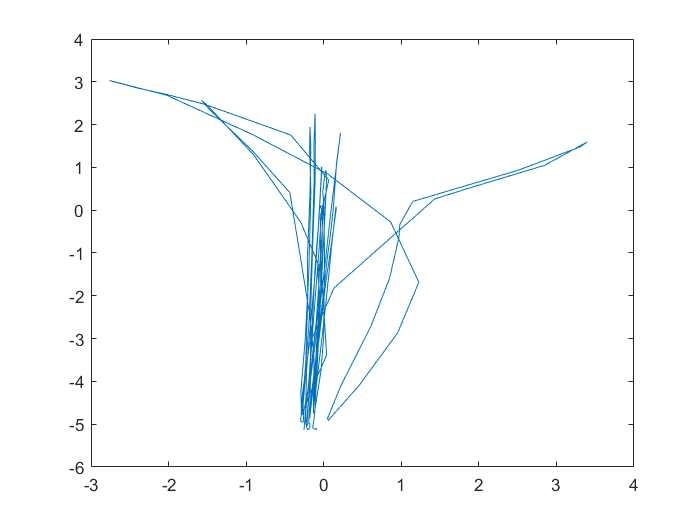

fwd_bwd = zeros(length(odom_index1));
side_wys = zeros(length(odom_index1));
pos = zeros(length(odom_index1),2);

for i =1:length(odom_index1) 
   fwd_bwd(i) = VarName8(odom_index1(i,1)+1,1);
   side_wys(i) = VarName7(odom_index1(i,1)+1,1);  
   pos(i,:) = [fwd_bwd(i) side_wys(i)];
end

figure(1)
plot(fwd_bwd,side_wys)

Initial state of the object

x = 5.3;
y = 3.6;
initialState = [x;0;y;-5];
KF = trackingKF('MotionModel','2D Constant Velocity','State',initialState);
T = 0.5;

Predicted state and corrected state

for k = 1:length(odom_index) 
    pstates(k,:) = predict(KF,T);
    cstates(k,:) = correct(KF,pos(k,:));
end

Plot the tracks

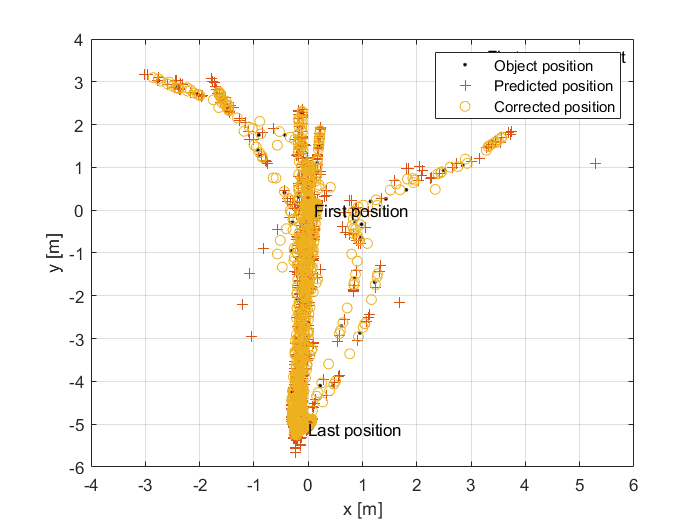

plot(pos(:,1),pos(:,2),'k.', pstates(:,1),pstates(:,3),'+', ...
    cstates(:,1),cstates(:,3),'o')
xlabel('x [m]')
ylabel('y [m]')
grid
xt  = [x-2 pos(1,1)+0.1 pos(end,1)+0.1];
yt = [y pos(1,2) pos(end,2)];
text(xt,yt,{'First measurement','First position','Last position'})
legend('Object position', 'Predicted position', 'Corrected position')